function [z, x_bb, t, nrepet, rolloff, span] = modulationQPSK(m, SNR_dB, nus, fp, Db, rolloff, span)
% modulationQPSK  QPSK avec mapping Gray, RRC shaping et ajout AWGN contrôlé
% Entrées :
%   m        : vecteur binaire ligne (longueur multiple de 2)
%   SNR_dB   : SNR en dB (mettre Inf pour aucun bruit)
%   nus      : fréquence d'échantillonnage (Hz)
%   fp       : fréquence porteuse (Hz)
%   Db       : débit binaire (bits/s)
%   rolloff  : roll-off du filtre RRC (ex: 0.25-0.5)
%   span     : span du filtre RRC en symboles (ex: 6)
% Sorties :
%   z        : signal modulé bruité (réel, en bande)
%   x_bb     : signal modulé sans bruit (réel, en bande)
%   t        : axe temps (s)
%   nrepet, rolloff, span : renvoyés pour usage côté démodulation

    if nargin < 8
        span = 6;
    end
    if nargin < 7
        rolloff = 0.35;
    end
    if nargin < 6 || isempty(Db)
        Db = 200;
    end
    if nargin < 5 || isempty(fp)
        fp = 200;
    end
    if nargin < 4 || isempty(nus)
        nus = 10000;
    end

    % === paramètres ===
    m = m(:).';                      % forcer ligne
    Nbits = length(m);
    assert(mod(Nbits,2)==0,'Le vecteur m doit contenir un nombre pair de bits');

    Rs = Db/2;                       % symbol rate (sym/s)
    nrepet = round(nus / Rs);        % échantillons par symbole
    Ts = 1/nus;

    % === Mapping Gray (bits -> I,Q) ===
    ms = reshape(m,2,[])';           % Nx2, chaque ligne [bI bQ]
    bI = ms(:,1);
    bQ = ms(:,2);
    % symboles QPSK Gray: I = 1-2*bI, Q = 1-2*bQ
    symbols = ( (1-2*bI) + 1i*(1-2*bQ) ) / sqrt(2); % normalisé

    % === upsample ===
    up = upsample(symbols, nrepet); % vecteur colonne (sparse), length = Nsymb*nrepet

    % === RRC shaping (root raised cosine) ===
    rrcFilter = rcosdesign(rolloff, span, nrepet, 'sqrt'); % vecteur ligne
    shaped = conv(up, rrcFilter(:), 'same');              % still column

    % === modulation porteuse (bande passante) ===
    shaped = shaped(:).';              % ligne
    Ntot = length(shaped);
    t = (0:Ntot-1) * Ts;
    x_bb = real(shaped).*cos(2*pi*fp*t) - imag(shaped).*sin(2*pi*fp*t); % signal sans bruit

    % === Ajout de bruit AWGN selon SNR ===
    if isfinite(SNR_dB)
        signal_power = mean(x_bb.^2);
        SNR_lin = 10^(SNR_dB/10);
        noise_power = signal_power / SNR_lin;
        z = x_bb + sqrt(noise_power) * randn(size(x_bb));
    else
        z = x_bb; % pas de bruit
    end
end

function [bits_recu, symbols_recu, opt_offset, phi_est] = demodulationQPSK_soft(z, nus, fp, Db, rolloff, span, nrepet)
% demodulationQPSK_soft  Démodulation QPSK cohérente avec recherche d'offset
% Entrées :
%   z       : signal reçu (réel, bande)
%   nus, fp, Db, rolloff, span : mêmes paramètres que pour modulation
%   nrepet  : échantillons par symbole (optionnel, sinon calculé)
% Sorties :
%   bits_recu : vecteur binaire estimé
%   symbols_recu : symboles complexes décodés (après rotation de phase)
%   opt_offset : offset choisi (0..nrepet-1)
%   phi_est : estimation de la phase porteuse (rad)

    if nargin < 8 || isempty(nrepet)
        Rs = Db/2;
        nrepet = round(nus / Rs);
    end

    % === forme vecteur ligne et temps ===
    z = z(:).';
    Ts = 1/nus;
    N = length(z);
    t = (0:N-1) * Ts;

    % === mélange cohérent (I/Q) ===
    i_rec = z .* cos(2*pi*fp*t);
    q_rec = -z .* sin(2*pi*fp*t);
    baseband = i_rec + 1i*q_rec;      % vecteur ligne

    % === matched filter RRC (même filtre) ===
    rrcFilter = rcosdesign(rolloff, span, nrepet, 'sqrt');
    rrcFilter = rrcFilter(:).';       % vecteur ligne
    rx_filtered = conv(baseband, rrcFilter, 'same'); % ligne

    % === compenser délai du filtre ===
    delay = span * nrepet / 2;  % en échantillons

    % === recherche de l'offset d'échantillonnage (0 .. nrepet-1)
    % on choisit l'offset qui maximise l'amplitude moyenne des symboles échantillonnés
    best_metric = -Inf;
    opt_offset = 0;
    for off = 0:(nrepet-1)
        idx_start = delay + 1 + off;
        idx_end = length(rx_filtered) - delay;
        if idx_start >= idx_end
            continue;
        end
        samples = rx_filtered(idx_start : nrepet : idx_end);
        metric = mean(abs(samples)); % on veut max amplitude (meilleur timing)
        if metric > best_metric
            best_metric = metric;
            opt_offset = off;
        end
    end

    % === échantillonnage final avec offset choisi ===
    idx_start = delay + 1 + opt_offset;
    idx_end = length(rx_filtered) - delay;
    symbols = rx_filtered(idx_start : nrepet : idx_end); % vecteur colonne

    % === normalisation amplitude (empirique) ===
    symbols = symbols(:); % colonne
    symbols = symbols / mean(abs(symbols)); % réduit scaling variable

    % === estimation de la phase résiduelle (méthode quatrième puissance) ===
    % Pour QPSK, (s * exp(-j*phi))^4 ≈ data^4 * exp(-j*4phi) -> moyenne enlève données
    phi_est = angle(mean(symbols.^4)) / 4;
    symbols_rot = symbols * exp(-1i * phi_est);

    % === décision (décodage Gray simple) ===
    % On utilise mapping: bI = (real < 0), bQ = (imag < 0)
    I = real(symbols_rot);
    Q = imag(symbols_rot);
    bI_hat = I < 0;
    bQ_hat = Q < 0;
    % reconstruire vecteur binaire (ordre [bI bQ] par symbole)
    bits_matrix = [bI_hat, bQ_hat];   % Nx2
    bits_recu = reshape(bits_matrix.', 1, []); % ligne

    symbols_recu = symbols_rot;       % pour inspection / constellation
end

% Paramètres
nus = 10000;
fp = 200;
Db = 200;
rolloff = 0.35;
span = 6;
SNR_dB = 20;    % change pour tester robustesse: 5, 10, 20, Inf (pas de bruit)

% Message binaire
Nbits = 2000;
m = randi([0 1], 1, Nbits);

% Modulation
[z, x_bb, t, nrepet, ~, ~] = modulationQPSK(m, SNR_dB, nus, fp, Db, rolloff, span);

% Démodulation
[bits_recu, symbols_recu, opt_offset, phi_est] = demodulationQPSK_soft(z, nus, fp, Db, rolloff, span, nrepet);

% Évaluation
nb = min(length(bits_recu), length(m));
nb_errors = sum(bits_recu(1:nb) ~= m(1:nb));
BER = nb_errors / nb;

fprintf('Opt offset = %d samples, phi_est = %.3f rad\n', opt_offset, phi_est);

Opt offset = 0 samples, phi_est = 0.785 rad


fprintf('BER = %g (%d erreurs sur %d bits)\n', BER, nb_errors, nb);

BER = 0.45674 (908 erreurs sur 1988 bits)


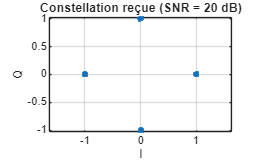


% Affichage constellation
figure;
plot(real(symbols_recu), imag(symbols_recu), '.');
axis equal; grid on;
title(sprintf('Constellation reçue (SNR = %g dB)', SNR_dB));
xlabel('I'); ylabel('Q');


m

m =      0     1     0     0     0     0     0     0     0     0     1     1     1     0     1     1     0     1     1     1     0     1     0     1     0     1     0     1     1     1     1     1     1     0     0     1     0     1     1     1     1     1     1     1     1     0     0     1     1     0


bits_recu

bits_recu = 1×1988 logical array
   0   1   0   1   1   0   0   0   1   1   0   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   0   1   1   1   1   1   0   1   1   1   0   0   0   1   1   1   0   0   0   1   1   0   0
